# Models for Syncrophasor with Step Discontinuities in Magnitude and Phase

## Introduction

This work is based upon the yet to be published work of Marcelo B. Martins et al.

The general equation for a sinusoidal function with magnitude step is:


$$y(t) = X_m[1+k_x u(t-\tau)]cos(\omega t + \phi)+ \eta(t)$$


and for phase step is:


$$y(t) = x_1cos(\omega t + \phi + k_a u (t - \tau ))+ \eta(t)$$


We will define a vector $$P = [x_1,x_2,x_3,\omega,\phi]$$

f0 = 60;    % nominal frequency
w = 2*pi()*f0;
phi = 0;
Xm = 1;
Kx = 0.1;   % 10% magnitude step
Ka = 0;     % phase step index
P = [Xm,Kx,Ka,w,phi];

Test system parameters:

Fs = 1024;
tStart = -2;
tEnd = 2;

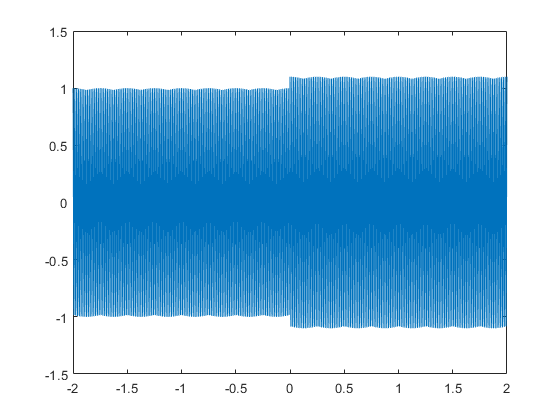

[t,y] = GenStepSignal(P,tStart,tEnd,Fs);
Y = real(y');
plot (t,Y);

function [t,y] = GenStepSignal(P,tStart,tEnd,Fs)

% Generate a time vector 
t = (tStart:1/Fs:tEnd)';

% generate an amplitude vector
Ain = zeros(length(t),1);
Ain = P(1)+Ain;
Ain(t >= 0) = Ain(t >= 0) * (1 + P(2));         % Magnitude Step

% generate a phase vector
Theta = zeros(length(t),1);
Theta = (P(4) * t) + P(5);                         % Fundamental and initial phase
Theta(t >= 0) = Theta(t>=0) + (P(3) * pi/180);  % Phase Step

y  = Ain .* exp(-1i.*Theta);

end